run AircraftData.mlx

Vanguard = struct with fields:
              MTOW: 147030
       WingLoading: 93.5500
              Wing: [1×1 struct]
          Fuselage: [1×1 struct]
      VerticalTail: [1×1 struct]
    HorizontalTail: [1×1 struct]


Vanguard = struct with fields:
              MTOW: 147030
       WingLoading: 93.5500
              Wing: [1×1 struct]
          Fuselage: [1×1 struct]
      VerticalTail: [1×1 struct]
    HorizontalTail: [1×1 struct]


Vanguard = struct with fields:
              MTOW: 147030
       WingLoading: 93.5500
              Wing: [1×1 struct]
          Fuselage: [1×1 struct]
      VerticalTail: [1×1 struct]
    HorizontalTail: [1×1 struct]


Vanguard = struct with fields:
              MTOW: 147030
       WingLoading: 93.5500
              Wing: [1×1 struct]
          Fuselage: [1×1 struct]
      VerticalTail: [1×1 struct]
    HorizontalTail: [1×1 struct]



%Flight Conditions
V = 350; %kts 
h = 25000; %ft
DynVisc = 3.2166*10^(-7); %Slug/ft-s CHANGES WITH ALT
MTOW = Vanguard.MTOW;
W = MTOW*0.946;

[TempRat, PresRat, DensRat, SpeedSound] = ISA(h);
V=V*1.688

V = 590.8000

M = V/SpeedSound

M = 0.5817


%Airfoil Parameters
Cla = 2*pi

Cla = 6.2832

Tmax = Vanguard.Wing.Airfoil.TMax

Tmax = 0.1500

LocMaxT = Vanguard.Wing.Airfoil.LocTMax

LocMaxT = 0.4000

PerLamFlow = Vanguard.Wing.Airfoil.PerLamFlow

PerLamFlow = 0.1000

CLDMin = Vanguard.Wing.Airfoil.CldMin

CLDMin = 0.1000


%Planform Parameters
S = Vanguard.Wing.S; %ft^2
b = Vanguard.Wing.b;
AR = Vanguard.Wing.AR;
TaperRatio = Vanguard.Wing.TaperRatio;
Q = 1.01

Q = 1.0100

SweepQuartC = Vanguard.Wing.QuarterChordSweep;

%Fuselage Parameters
Df = Vanguard.Fuselage.Diameter; %ft
LNose = Vanguard.Fuselage.NoseLength; %ft
LMid = Vanguard.Fuselage.CargoLength; %ft
LTail = Vanguard.Fuselage.TailLength %ft

LTail = 37.3000

DBase = Vanguard.Fuselage.BaseDia %ft

DBase = 4

ABase = Vanguard.Fuselage.ABase

ABase = 12.5664

UpsweepAngle = Vanguard.Fuselage.UpsweepAngle; %rad

%Vertical Tail Parameters NOTE: Half Wing
Sv = Vanguard.VerticalTail.S; %ft^2
ARv = Vanguard.VerticalTail.AR;
TaperRatiov = Vanguard.VerticalTail.TaperRatio;
bv = Vanguard.VerticalTail.b;
QVt = 1.05;
LocMaxTv = Vanguard.VerticalTail.LocTMax;
Tmaxv = Vanguard.VerticalTail.TMax

Tmaxv = 0.1200


%Horizontal Tail Parameters
Sh = Vanguard.HorizontalTail.S; %ft^2
ARh = Vanguard.HorizontalTail.AR;
TaperRatioh = Vanguard.HorizontalTail.TaperRatio;
bh = Vanguard.HorizontalTail.b;
QHt = 1.05;
LocMaxTh = Vanguard.HorizontalTail.LocTMax;
Tmaxh = Vanguard.HorizontalTail.TMax

Tmaxh = 0.1200


%Nacelle Parameters
LNacelle = 78/12;
DNacelle = 34/12;

%Blister Parameters
LBlister = 16;
DBlister = 3;

%Induced Drag Factor

Ne = 0; %Num of engines ON TOP of Wing
TaperFunc = 0.005*(1+1.5*(TaperRatio-0.6)^2)

TaperFunc = 0.0053

K = (1+(0.142+TaperFunc*AR*(10*Tmax)^(0.33))/(cosd(SweepQuartC)^2)+(0.1*(3*Ne+1))/((4+AR)^0.8))*(1+0.12*M^6)/(pi*AR);
e = 1/(K*AR*pi);

[CDoWing] = WingZeroLiftDrag(V,Q,TaperRatio,DynVisc,0,S,AR,b,h,LocMaxT,Df,PerLamFlow,Tmax);

Vanguard = struct with fields:
           MTOW: 147030
    WingLoading: 93.5500
           Wing: [1×1 struct]


Vanguard = struct with fields:
              MTOW: 147030
       WingLoading: 93.5500
              Wing: [1×1 struct]
          Fuselage: [1×1 struct]
      VerticalTail: [1×1 struct]
    HorizontalTail: [1×1 struct]


Vanguard = struct with fields:
              MTOW: 147030
       WingLoading: 93.5500
              Wing: [1×1 struct]
          Fuselage: [1×1 struct]
      VerticalTail: [1×1 struct]
    HorizontalTail: [1×1 struct]


Vanguard = struct with fields:
              MTOW: 147030
       WingLoading: 93.5500
              Wing: [1×1 struct]
          Fuselage: [1×1 struct]
      VerticalTail: [1×1 struct]
    HorizontalTail: [1×1 struct]


V = 997.2704

M = 0.9820

Cr = 16.6139

Cmac = 13.7899

Ymac = 25.2857

SweepMaxT = -1.6625

Vanguard = struct with fields:
           MTOW: 147030
    WingLoading: 93.5500
           Wing: [1×1 struct]


Vanguard = struct with fields:
              MTOW: 147030
       WingLoading: 93.5500
              Wing: [1×1 struct]
          Fuselage: [1×1 struct]
      VerticalTail: [1×1 struct]
    HorizontalTail: [1×1 struct]


Vanguard = struct with fields:
              MTOW: 147030
       WingLoading: 93.5500
              Wing: [1×1 struct]
          Fuselage: [1×1 struct]
      VerticalTail: [1×1 struct]
    HorizontalTail: [1×1 struct]


Vanguard = struct with fields:
              MTOW: 147030
       WingLoading: 93.5500
              Wing: [1×1 struct]
          Fuselage: [1×1 struct]
      VerticalTail: [1×1 struct]
    HorizontalTail: [1×1 struct]


Re = 7.6785e+07

SweepMaxT = -1.6625

Cf = 0.0022

FF = 1.7035

Swet = 2.6892e+03

CDo = 0.0064


[CDoHt] = WingZeroLiftDrag(V,QHt,TaperRatioh,DynVisc,0,Sh,ARh,bh,h,LocMaxTh,0,PerLamFlow,Tmaxh);

Vanguard = struct with fields:
           MTOW: 147030
    WingLoading: 93.5500
           Wing: [1×1 struct]


Vanguard = struct with fields:
              MTOW: 147030
       WingLoading: 93.5500
              Wing: [1×1 struct]
          Fuselage: [1×1 struct]
      VerticalTail: [1×1 struct]
    HorizontalTail: [1×1 struct]


Vanguard = struct with fields:
              MTOW: 147030
       WingLoading: 93.5500
              Wing: [1×1 struct]
          Fuselage: [1×1 struct]
      VerticalTail: [1×1 struct]
    HorizontalTail: [1×1 struct]


Vanguard = struct with fields:
              MTOW: 147030
       WingLoading: 93.5500
              Wing: [1×1 struct]
          Fuselage: [1×1 struct]
      VerticalTail: [1×1 struct]
    HorizontalTail: [1×1 struct]


V = 997.2704

M = 0.9820

Cr = 16.6139

Cmac = 13.7899

Ymac = 9.5530

SweepMaxT = -1.6531

Vanguard = struct with fields:
           MTOW: 147030
    WingLoading: 93.5500
           Wing: [1×1 struct]


Vanguard = struct with fields:
              MTOW: 147030
       WingLoading: 93.5500
              Wing: [1×1 struct]
          Fuselage: [1×1 struct]
      VerticalTail: [1×1 struct]
    HorizontalTail: [1×1 struct]


Vanguard = struct with fields:
              MTOW: 147030
       WingLoading: 93.5500
              Wing: [1×1 struct]
          Fuselage: [1×1 struct]
      VerticalTail: [1×1 struct]
    HorizontalTail: [1×1 struct]


Vanguard = struct with fields:
              MTOW: 147030
       WingLoading: 93.5500
              Wing: [1×1 struct]
          Fuselage: [1×1 struct]
      VerticalTail: [1×1 struct]
    HorizontalTail: [1×1 struct]


Re = 7.6785e+07

SweepMaxT = -1.6531

Cf = 0.0022

FF = 1.6379

Swet = 815.7600

CDo = 0.0076


CDoHt = CDoHt*Sh/S;

[CDoVt] = WingZeroLiftDrag(V,QVt,TaperRatiov,DynVisc,0,Sv,ARv,bv,h,LocMaxTv,0,PerLamFlow,Tmaxv);

Vanguard = struct with fields:
           MTOW: 147030
    WingLoading: 93.5500
           Wing: [1×1 struct]


Vanguard = struct with fields:
              MTOW: 147030
       WingLoading: 93.5500
              Wing: [1×1 struct]
          Fuselage: [1×1 struct]
      VerticalTail: [1×1 struct]
    HorizontalTail: [1×1 struct]


Vanguard = struct with fields:
              MTOW: 147030
       WingLoading: 93.5500
              Wing: [1×1 struct]
          Fuselage: [1×1 struct]
      VerticalTail: [1×1 struct]
    HorizontalTail: [1×1 struct]


Vanguard = struct with fields:
              MTOW: 147030
       WingLoading: 93.5500
              Wing: [1×1 struct]
          Fuselage: [1×1 struct]
      VerticalTail: [1×1 struct]
    HorizontalTail: [1×1 struct]


V = 997.2704

M = 0.9820

Cr = 16.6139

Cmac = 13.7899

Ymac = 10.3920

SweepMaxT = -1.8842

Vanguard = struct with fields:
           MTOW: 147030
    WingLoading: 93.5500
           Wing: [1×1 struct]


Vanguard = struct with fields:
              MTOW: 147030
       WingLoading: 93.5500
              Wing: [1×1 struct]
          Fuselage: [1×1 struct]
      VerticalTail: [1×1 struct]
    HorizontalTail: [1×1 struct]


Vanguard = struct with fields:
              MTOW: 147030
       WingLoading: 93.5500
              Wing: [1×1 struct]
          Fuselage: [1×1 struct]
      VerticalTail: [1×1 struct]
    HorizontalTail: [1×1 struct]


Vanguard = struct with fields:
              MTOW: 147030
       WingLoading: 93.5500
              Wing: [1×1 struct]
          Fuselage: [1×1 struct]
      VerticalTail: [1×1 struct]
    HorizontalTail: [1×1 struct]


Re = 7.6785e+07

SweepMaxT = -1.8842

Cf = 0.0022

FF = 1.6378

Swet = 1.2236e+03

CDo = 0.0076


CDoVt = CDoVt*Sv/S/2;

[CDoFuse] = ParaDragFuse(h,V,LMid,LNose,LTail,Df,DynVisc,S);

Cf = 0.0018

FF = 1.2662

SWet = 4.1586e+03

CDo = 0.0060


[CDoNacelle] = 8*ParaDragNacelle(h,V,LNacelle,DNacelle,DynVisc,S);

Re = 2.1442e+07

Cf = 0.0024

FF = 1.1526

SWet = 57.8577

CDo = 1.5553e-04


[CDoBlisters] = ParaDragNacelle(h,V,LBlister,DBlister,DynVisc,S);

Re = 5.2779e+07

Cf = 0.0021

FF = 1.0656

SWet = 150.7964

CDo = 3.2519e-04


UpSweepDrag = 3.83*UpsweepAngle^2.5*pi*Df^2/4/S;

CDoCamber = e/(1-e)*K*CLDMin^2;

BaseDrag = (0.1+0.1222*M^8)*ABase/S;

CDoTotal = CDoWing + CDoHt + CDoVt + CDoFuse + UpSweepDrag + BaseDrag + CDoNacelle + CDoCamber;




CL = -0.5:0.01:1.5

CL =    -0.5000   -0.4900   -0.4800   -0.4700   -0.4600   -0.4500   -0.4400   -0.4300   -0.4200   -0.4100   -0.4000   -0.3900   -0.3800   -0.3700   -0.3600   -0.3500   -0.3400   -0.3300   -0.3200   -0.3100   -0.3000   -0.2900   -0.2800   -0.2700   -0.2600   -0.2500   -0.2400   -0.2300   -0.2200   -0.2100   -0.2000   -0.1900   -0.1800   -0.1700   -0.1600   -0.1500   -0.1400   -0.1300   -0.1200   -0.1100   -0.1000   -0.0900   -0.0800   -0.0700   -0.0600   -0.0500   -0.0400   -0.0300   -0.0200   -0.0100



LDMax = 0;

for x=1:201
    
   CD(x) = CDoTotal + K*CL(x)^2;
   
   if CL(x)/CD(x)>LDMax
       
       LDMax = CL(x)/CD(x)
       
   end
   
end

LDMax = 0.4064

LDMax = 0.8125

LDMax = 1.2176

LDMax = 1.6215

LDMax = 2.0236

LDMax = 2.4236

LDMax = 2.8211

LDMax = 3.2157

LDMax = 3.6069

LDMax = 3.9944

LDMax = 4.3778

LDMax = 4.7568

LDMax = 5.1310

LDMax = 5.5001

LDMax = 5.8638

LDMax = 6.2218

LDMax = 6.5739

LDMax = 6.9197

LDMax = 7.2591

LDMax = 7.5918

LDMax = 7.9177

LDMax = 8.2364

LDMax = 8.5480

LDMax = 8.8522

LDMax = 9.1489

LDMax = 9.4380

LDMax = 9.7194

LDMax = 9.9931

LDMax = 10.2589

LDMax = 10.5169

LDMax = 10.7670

LDMax = 11.0093

LDMax = 11.2436

LDMax = 11.4701

LDMax = 11.6887

LDMax = 11.8996

LDMax = 12.1027

LDMax = 12.2982

LDMax = 12.4861

LDMax = 12.6665

LDMax = 12.8395

LDMax = 13.0052

LDMax = 13.1636

LDMax = 13.3151

LDMax = 13.4595

LDMax = 13.5972

LDMax = 13.7281

LDMax = 13.8525

LDMax = 13.9705

LDMax = 14.0822

LDMax = 14.1877

LDMax = 14.2873

LDMax = 14.3811

LDMax = 14.4692

LDMax = 14.5517

LDMax = 14.6288

LDMax = 14.7007

LDMax = 14.7676

LDMax = 14.8294

LDMax = 14.8865

LDMax = 14.9390

LDMax = 14.9869

LDMax = 15.0305

LDMax = 15.0699

LDMax = 15.1052

LDMax = 15.1365

LDMax = 15.1641

LDMax = 15.1879

LDMax = 15.2083

LDMax = 15.2252

LDMax = 15.2388

LDMax = 15.2492

LDMax = 15.2566

LDMax = 15.2611

LDMax = 15.2627


Line1 = [0]

Line1 = 0


% K2 = 1/(0.987*pi*AR)
% 
% LDMax2 = 0;
% 
% for x=1:201
%     
%    CD2(x) = CDoTotal2 + K2*CL(x)^2;
%    
%    if CL(x)/CD(x)>LDMax2
%        
%        LDMax2 = CL(x)/CD2(x)
%        
%    end
%    
% end

plot (CD,CL)

xlabel('Drag Coefficient, {\it C_{D}}')
ylabel('Lift Coefficient, {\it C_{L}}')
grid on
grid minor
hold on
ax = gca;
ax.XLim = [0 0.1152]

ax =   Axes with properties:

             XLim: [0 0.1152]
             YLim: [-0.5000 1.5000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1163 0.7750 0.8087]
            Units: 'normalized'

  Show all properties


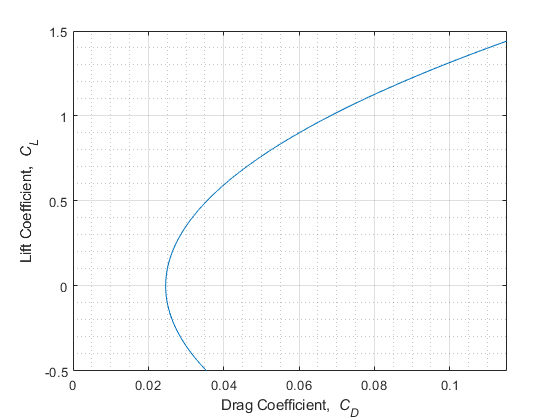

%ax.XAxisLocation = 'origin';
hold off

LDMax

LDMax = 15.2627


DynViscSL = 3.737*10^(-7)

DynViscSL = 3.7370e-07

Swf = 1100

Swf = 1100

%%%%%%%%%%%%%%%%%%%%%
% Landing and Takeoff
%%%%%%%%%%%%%%%%%%%%%

[CDoWingSL] = WingZeroLiftDrag(100,Q,TaperRatio,DynViscSL,0,S,AR,b,0,LocMaxT,Df,PerLamFlow,Tmax);

Vanguard = struct with fields:
           MTOW: 147030
    WingLoading: 93.5500
           Wing: [1×1 struct]


Vanguard = struct with fields:
              MTOW: 147030
       WingLoading: 93.5500
              Wing: [1×1 struct]
          Fuselage: [1×1 struct]
      VerticalTail: [1×1 struct]
    HorizontalTail: [1×1 struct]


Vanguard = struct with fields:
              MTOW: 147030
       WingLoading: 93.5500
              Wing: [1×1 struct]
          Fuselage: [1×1 struct]
      VerticalTail: [1×1 struct]
    HorizontalTail: [1×1 struct]


Vanguard = struct with fields:
              MTOW: 147030
       WingLoading: 93.5500
              Wing: [1×1 struct]
          Fuselage: [1×1 struct]
      VerticalTail: [1×1 struct]
    HorizontalTail: [1×1 struct]


V = 168.8000

M = 0.1513

Cr = 16.6139

Cmac = 13.7899

Ymac = 25.2857

SweepMaxT = -1.6625

Vanguard = struct with fields:
           MTOW: 147030
    WingLoading: 93.5500
           Wing: [1×1 struct]


Vanguard = struct with fields:
              MTOW: 147030
       WingLoading: 93.5500
              Wing: [1×1 struct]
          Fuselage: [1×1 struct]
      VerticalTail: [1×1 struct]
    HorizontalTail: [1×1 struct]


Vanguard = struct with fields:
              MTOW: 147030
       WingLoading: 93.5500
              Wing: [1×1 struct]
          Fuselage: [1×1 struct]
      VerticalTail: [1×1 struct]
    HorizontalTail: [1×1 struct]


Vanguard = struct with fields:
              MTOW: 147030
       WingLoading: 93.5500
              Wing: [1×1 struct]
          Fuselage: [1×1 struct]
      VerticalTail: [1×1 struct]
    HorizontalTail: [1×1 struct]


Re = 2.4992e+07

SweepMaxT = -1.6625

Cf = 0.0024

FF = 1.2165

Swet = 2.6892e+03

CDo = 0.0050


[CDoHtSL] = WingZeroLiftDrag(100,QHt,TaperRatioh,DynViscSL,0,Sh,ARh,bh,0,LocMaxTh,0,PerLamFlow,Tmaxh);

Vanguard = struct with fields:
           MTOW: 147030
    WingLoading: 93.5500
           Wing: [1×1 struct]


Vanguard = struct with fields:
              MTOW: 147030
       WingLoading: 93.5500
              Wing: [1×1 struct]
          Fuselage: [1×1 struct]
      VerticalTail: [1×1 struct]
    HorizontalTail: [1×1 struct]


Vanguard = struct with fields:
              MTOW: 147030
       WingLoading: 93.5500
              Wing: [1×1 struct]
          Fuselage: [1×1 struct]
      VerticalTail: [1×1 struct]
    HorizontalTail: [1×1 struct]


Vanguard = struct with fields:
              MTOW: 147030
       WingLoading: 93.5500
              Wing: [1×1 struct]
          Fuselage: [1×1 struct]
      VerticalTail: [1×1 struct]
    HorizontalTail: [1×1 struct]


V = 168.8000

M = 0.1513

Cr = 16.6139

Cmac = 13.7899

Ymac = 9.5530

SweepMaxT = -1.6531

Vanguard = struct with fields:
           MTOW: 147030
    WingLoading: 93.5500
           Wing: [1×1 struct]


Vanguard = struct with fields:
              MTOW: 147030
       WingLoading: 93.5500
              Wing: [1×1 struct]
          Fuselage: [1×1 struct]
      VerticalTail: [1×1 struct]
    HorizontalTail: [1×1 struct]


Vanguard = struct with fields:
              MTOW: 147030
       WingLoading: 93.5500
              Wing: [1×1 struct]
          Fuselage: [1×1 struct]
      VerticalTail: [1×1 struct]
    HorizontalTail: [1×1 struct]


Vanguard = struct with fields:
              MTOW: 147030
       WingLoading: 93.5500
              Wing: [1×1 struct]
          Fuselage: [1×1 struct]
      VerticalTail: [1×1 struct]
    HorizontalTail: [1×1 struct]


Re = 2.4992e+07

SweepMaxT = -1.6531

Cf = 0.0024

FF = 1.1696

Swet = 815.7600

CDo = 0.0059


CDoHtSL = CDoHtSL*Sh/S

CDoHtSL = 0.0015


[CDoVtSL] = WingZeroLiftDrag(100,QVt,TaperRatiov,DynViscSL,0,Sv,ARv,bv,0,LocMaxTv,0,PerLamFlow,Tmaxv);

Vanguard = struct with fields:
           MTOW: 147030
    WingLoading: 93.5500
           Wing: [1×1 struct]


Vanguard = struct with fields:
              MTOW: 147030
       WingLoading: 93.5500
              Wing: [1×1 struct]
          Fuselage: [1×1 struct]
      VerticalTail: [1×1 struct]
    HorizontalTail: [1×1 struct]


Vanguard = struct with fields:
              MTOW: 147030
       WingLoading: 93.5500
              Wing: [1×1 struct]
          Fuselage: [1×1 struct]
      VerticalTail: [1×1 struct]
    HorizontalTail: [1×1 struct]


Vanguard = struct with fields:
              MTOW: 147030
       WingLoading: 93.5500
              Wing: [1×1 struct]
          Fuselage: [1×1 struct]
      VerticalTail: [1×1 struct]
    HorizontalTail: [1×1 struct]


V = 168.8000

M = 0.1513

Cr = 16.6139

Cmac = 13.7899

Ymac = 10.3920

SweepMaxT = -1.8842

Vanguard = struct with fields:
           MTOW: 147030
    WingLoading: 93.5500
           Wing: [1×1 struct]


Vanguard = struct with fields:
              MTOW: 147030
       WingLoading: 93.5500
              Wing: [1×1 struct]
          Fuselage: [1×1 struct]
      VerticalTail: [1×1 struct]
    HorizontalTail: [1×1 struct]


Vanguard = struct with fields:
              MTOW: 147030
       WingLoading: 93.5500
              Wing: [1×1 struct]
          Fuselage: [1×1 struct]
      VerticalTail: [1×1 struct]
    HorizontalTail: [1×1 struct]


Vanguard = struct with fields:
              MTOW: 147030
       WingLoading: 93.5500
              Wing: [1×1 struct]
          Fuselage: [1×1 struct]
      VerticalTail: [1×1 struct]
    HorizontalTail: [1×1 struct]


Re = 2.4992e+07

SweepMaxT = -1.8842

Cf = 0.0024

FF = 1.1696

Swet = 1.2236e+03

CDo = 0.0059


CDoVtSL = CDoVtSL*Sv/S/2;

[CDoFuseSL] = ParaDragFuse(0,100,LMid,LNose,LTail,Df,DynViscSL,S);

Cf = 0.0021

FF = 1.2662

SWet = 4.1586e+03

CDo = 0.0071


[CDoNacelleSL] = 8*ParaDragNacelle(0,100,LNacelle,DNacelle,DynViscSL,S);

Re = 6.9787e+06

Cf = 0.0029

FF = 1.1526

SWet = 57.8577

CDo = 1.8518e-04


[CDoBlistersSL] = ParaDragNacelle(0,100,LBlister,DBlister,DynViscSL,S);

Re = 1.7178e+07

Cf = 0.0025

FF = 1.0656

SWet = 150.7964

CDo = 3.8484e-04

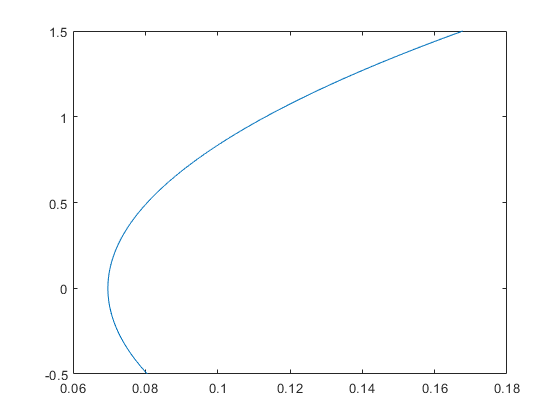


CDo_CleanSL = CDoWingSL + CDoHtSL + CDoVtSL + CDoFuseSL + UpSweepDrag + BaseDrag + CDoNacelleSL + CDoCamber;

k1 = 1.75;

k2Landing = 0.0375;

k2TO = 0.0125;

dCDoLanding = k1*k2Landing*Swf/S;

dCDoTO = k1*k2TO*Swf/S;

for x=1:201
    
   CDLanding(x) = CDo_CleanSL+dCDoLanding + K*CL(x)^2;

   CDTO(x) = CDo_CleanSL+dCDoTO + K*CL(x)^2;
    
end



plot (CDLanding,CL)

plot (CDTO,CL)

legend('Cruise','Landing', 'Takeoff')

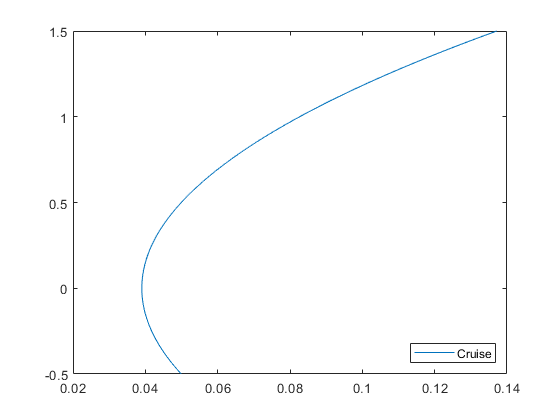

legend('Location','southeast')

hold off